# Evaluate the NN demosaic network on the MTF and LSF

The MTF and spread of the LSF of the restormer networks are close to the ideal, given the lens and sensor sampling.

But, oddly, the phase of the LSF does not always match. There can be a shift in the position of the LSF under dark conditions, even though the MTF is close to ideal.  

The standard ip processing is below the ideal.  

To remember:  The MTF50 estimate is not very stable w.r.t. noise.  It can vary a fair amount and we should really repeat it many times and take the median or mode when publishing.

## Initialize ISET

ieInit;

## Create the sensors

sensorRGBW = sensorCreate('ar0132at',[],'rgbw');
sensorRGB  = sensorCreate('ar0132at',[],'rgb');
sensorRGB  = sensorSet(sensorRGB,'exp time',1/30);
sensorRGBW = sensorSet(sensorRGBW,'exp time',1/30);

sensorRGB  = sensorSet(sensorRGB,'pixel size constant fill factor',3e-6);
sensorRGB  = sensorSet(sensorRGB, 'sensor size', [512, 512]);
sensorRGBW = sensorSet(sensorRGBW,'pixel size constant fill factor',3e-6);
sensorRGBW = sensorSet(sensorRGBW, 'sensor size', [512, 512]);

## Slanted bar for the MTF

scene = sceneCreate('slanted bar', 500);
oi = oiCreate;
oi = oiCompute(oi, scene,'crop',true,'pixel size', 3e-6);

## Match the sensors to the OI

sensorRGB = sensorSet(sensorRGB,'match oi',oi);
sensorRGBW = sensorSet(sensorRGBW,'match oi',oi);

% Bright to dim from 0.25 lux to 2.4 lux
lux = logspace(-.5,0.5,3);
mtfPlot = 'none';

## Calculate the LSF and MTF

Black border detected


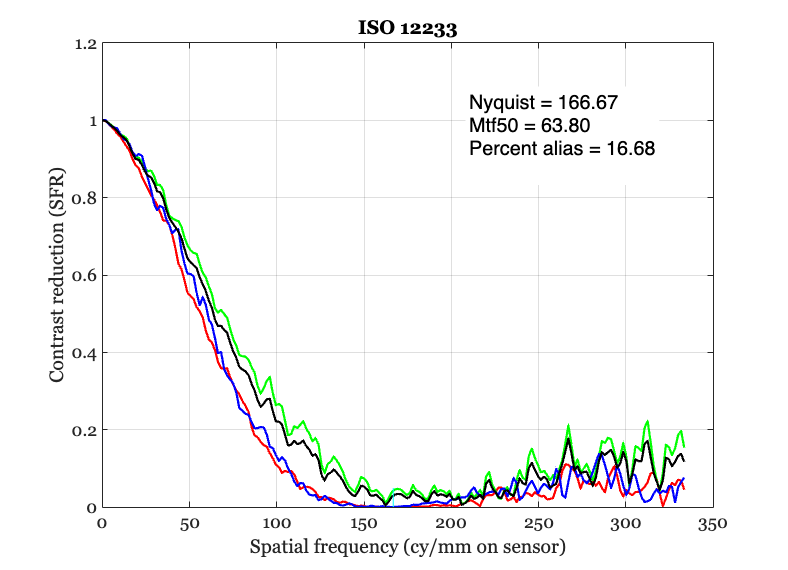

INFO: Input image is RGB
INFO: Demosaicing is successfully completed.


Black border detected
 *** Warning: low clipping in record 1
 *** Warning: low clipping in record 2
 *** Warning: low clipping in record 3


Fraction low data: 0.001
Fraction low data: 0.000
Fraction low data: 0.000
Fraction high data: 0.000
Fraction high data: 0.000
Fraction high data: 0.000


INFO: Input image is RGBW
INFO: Demosaicing is successfully completed.


Black border detected
 *** Warning: low clipping in record 3


Fraction low data: 0.000
Fraction low data: 0.000
Fraction low data: 0.000
Fraction high data: 0.000
Fraction high data: 0.000
Fraction high data: 0.000


Black border detected


Black border detected


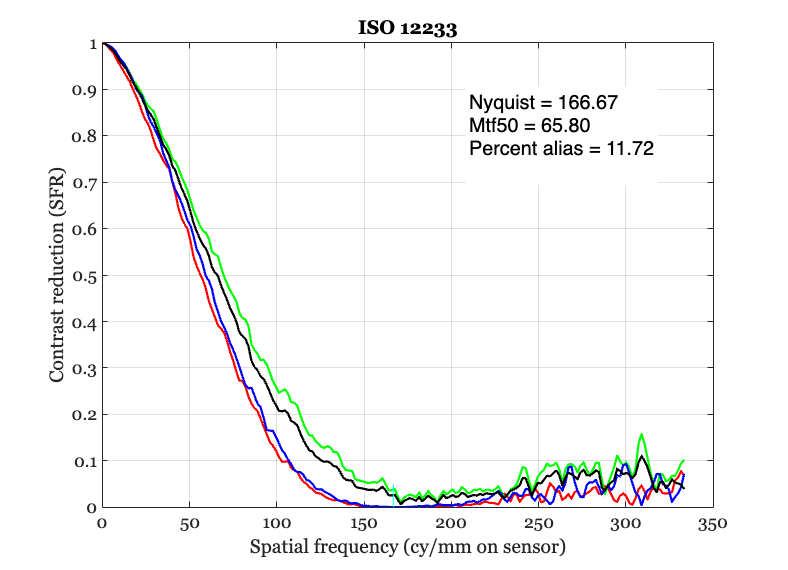

INFO: Input image is RGB
INFO: Demosaicing is successfully completed.


Black border detected
 *** Warning: low clipping in record 1


Fraction low data: 0.000
Fraction low data: 0.000
Fraction low data: 0.000
Fraction high data: 0.000
Fraction high data: 0.000
Fraction high data: 0.000


INFO: Input image is RGBW
INFO: Demosaicing is successfully completed.


Black border detected
 *** Warning: low clipping in record 1
 *** Warning: low clipping in record 2
 *** Warning: low clipping in record 3


Fraction low data: 0.001
Fraction low data: 0.000
Fraction low data: 0.080
Fraction high data: 0.000
Fraction high data: 0.000
Fraction high data: 0.000


Black border detected


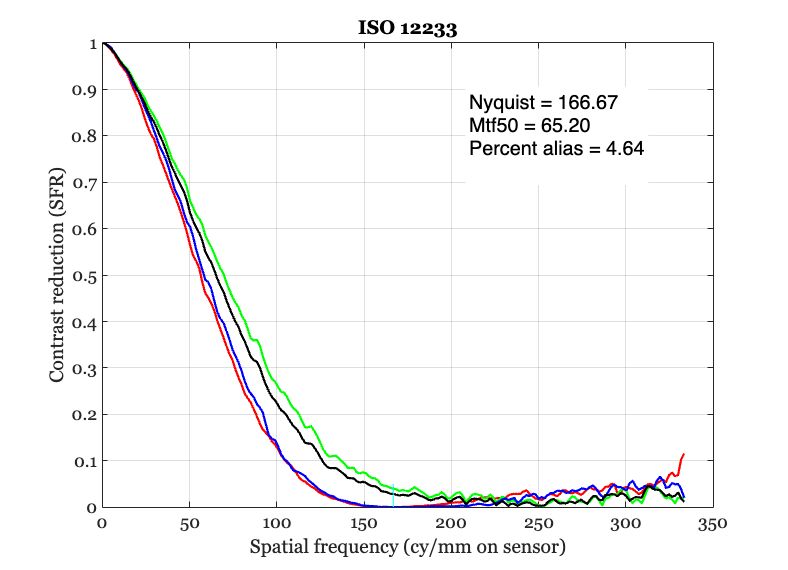

INFO: Input image is RGB
INFO: Demosaicing is successfully completed.


Black border detected
 *** Warning: low clipping in record 1
 *** Warning: low clipping in record 2
 *** Warning: low clipping in record 3


Fraction low data: 0.000
Fraction low data: 0.000
Fraction low data: 0.000
Fraction high data: 0.000
Fraction high data: 0.000
Fraction high data: 0.000


INFO: Input image is RGBW
INFO: Demosaicing is successfully completed.


Black border detected
 *** Warning: low clipping in record 1
 *** Warning: low clipping in record 2
 *** Warning: low clipping in record 3


Fraction low data: 0.262
Fraction low data: 0.252
Fraction low data: 0.363
Fraction high data: 0.000
Fraction high data: 0.000
Fraction high data: 0.000


ip = ipCreate;
for ii = 1:numel(lux)
    oi = oiAdjustIlluminance(oi, lux(ii));

    % rgb and standard processing
    thisSensorRGB = sensorCompute(sensorRGB,oi);
    ipRGB = ipCompute(ip, thisSensorRGB);
    mtfRGB = ieISO12233(ipRGB,thisSensorRGB);

    if ~isempty(mtfRGB)
        % When the level is very low, we sometimes fail.  So this
        % check is here.

        % rgb and restormer
        ipRGBNN = ipCompute(ip, thisSensorRGB, 'network demosaic','ar0132at-rgb');
        mtfRGBNN = ieISO12233(ipRGBNN,thisSensorRGB,mtfPlot);
        % ipWindow(ipRGBNN); rgbNNImg = ipGet(ipRGBNN, 'srgb');

        % rgbw using restormer
        thisSensorRGBW = sensorCompute(sensorRGBW,oi);
        ipRGBWNN = ipCompute(ip,thisSensorRGBW, 'network demosaic','ar0132at-rgbw');
        mtfRGBWNN = ieISO12233(ipRGBWNN,thisSensorRGBW,mtfPlot);

        if ii==1
            % Process once to get the ideal.
            sensorI = sensorCreateIdeal('match',sensorRGB);
            sensorI = sensorCompute(sensorI,oi);
            
            gtImg(:,:,1) = sensorI(1).data.volts;
            gtImg(:,:,2) = sensorI(2).data.volts;
            gtImg(:,:,3) = sensorI(3).data.volts;

            ipIdeal = ipRGB;
            ipIdeal = ipSet(ipIdeal, 'demosaic method', 'skip');
            ipIdeal = ipSet(ipIdeal, 'transform method', 'current');
            ipIdeal = ipSet(ipIdeal, 'sensor space', gtImg);

            % Compute the final image processing
            ipIdeal = ipCompute(ipIdeal, thisSensorRGB);
            mtfIdeal = ieISO12233(ipIdeal,thisSensorRGB,mtfPlot);
        end

## Plot MTF 

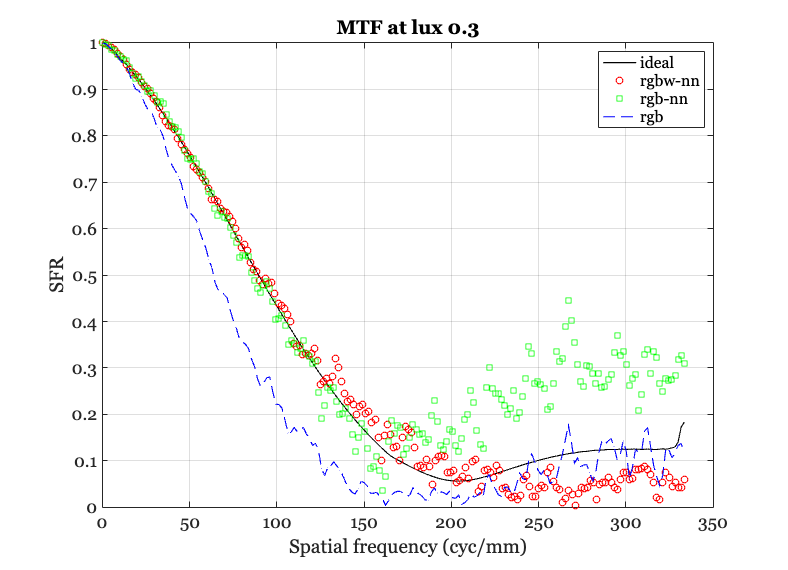

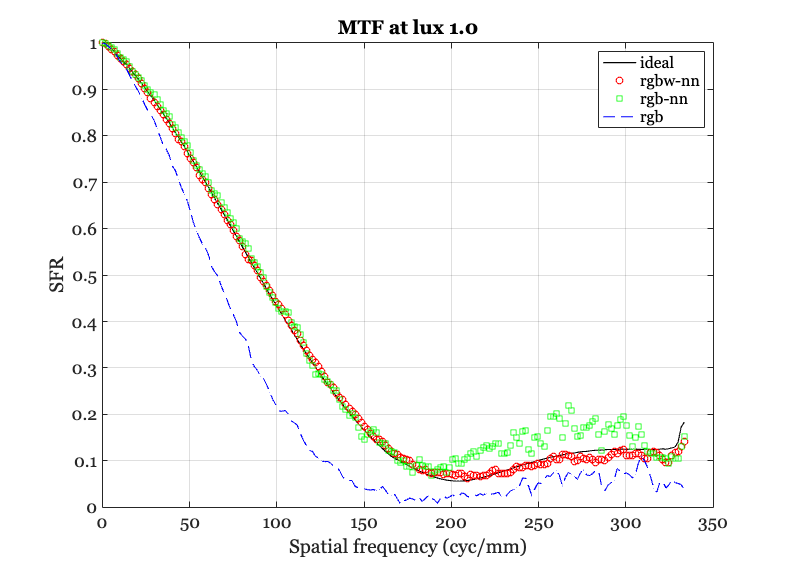

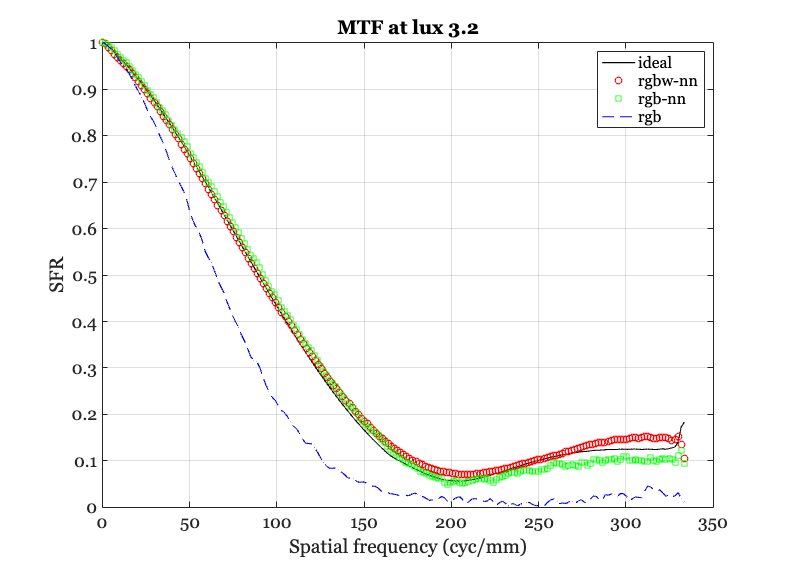

        ieNewGraphWin;
        plot(mtfIdeal.freq,mtfIdeal.mtf(:,4),'k-'); hold on;
        plot(mtfRGBWNN.freq,mtfRGBWNN.mtf(:,4),'ro'); hold on;
        plot(mtfRGBNN.freq,mtfRGBNN.mtf(:,4),'gs'); hold on;
        plot(mtfRGB.freq,mtfRGB.mtf(:,4),'b--'); hold on;
        grid on;
        xlabel('Spatial frequency (cyc/mm)'); ylabel('SFR');
        legend({'ideal','rgbw-nn','rgb-nn','rgb'});
        title(sprintf('MTF at lux %.1f',lux(ii)));
        drawnow;

## Plot Line spread

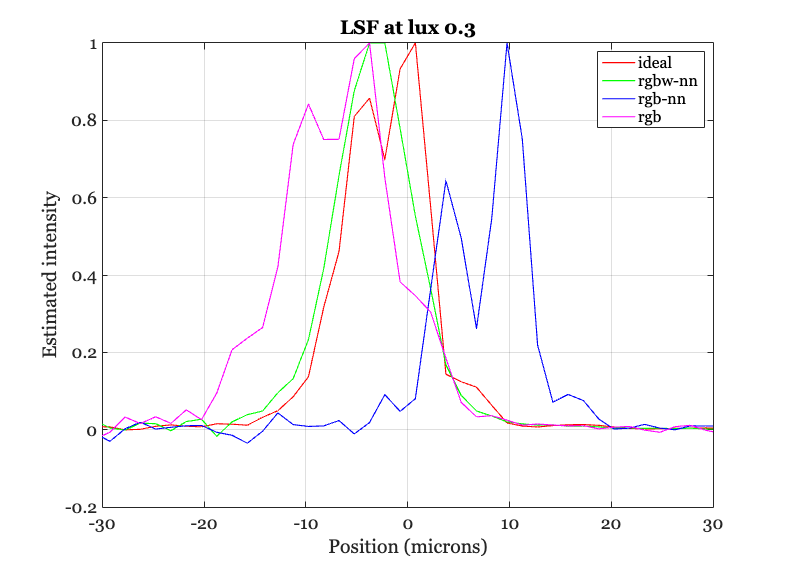

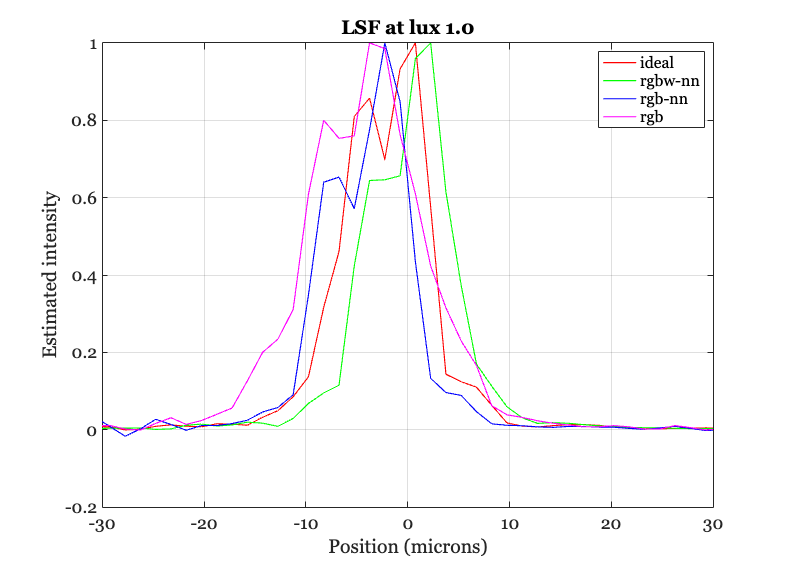

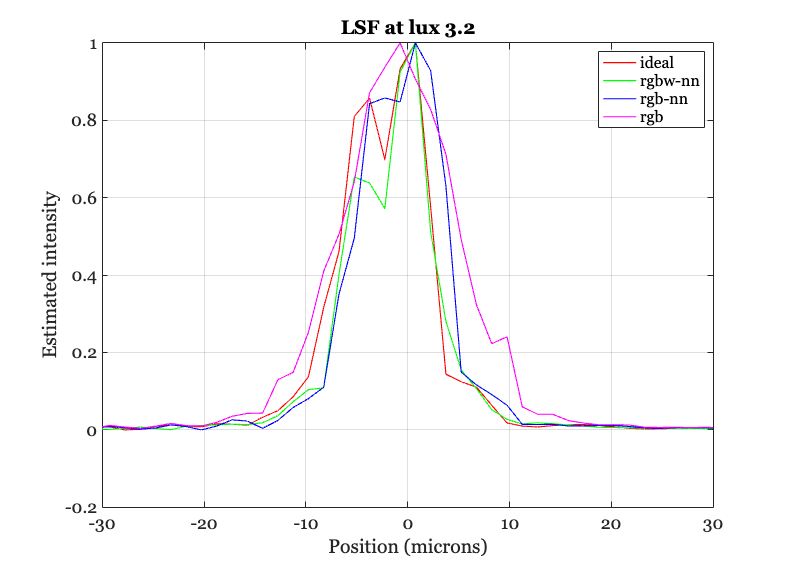

        ieNewGraphWin;
        plot(mtfIdeal.lsfx*1e3,mtfIdeal.lsf); hold on;
        plot(mtfRGBWNN.lsfx*1e3,mtfRGBWNN.lsf); hold on;
        plot(mtfRGBNN.lsfx*1e3,mtfRGBNN.lsf); hold on;
        plot(mtfRGB.lsfx*1e3,mtfRGB.lsf); hold on;
        set(gca,'xlim',[-30 30]); grid on;
        xlabel('Position (microns)'); ylabel('Estimated intensity')
        title('Edge spreads and LSF');
        set(gca,'xtick',-80:10:80); hold on;
        legend({'ideal','rgbw-nn','rgb-nn','rgb'});
        title(sprintf('LSF at lux %.1f',lux(ii)));
        drawnow;
    end

end